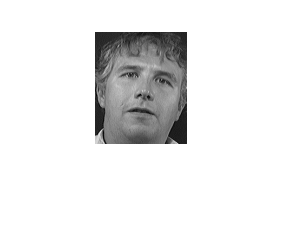

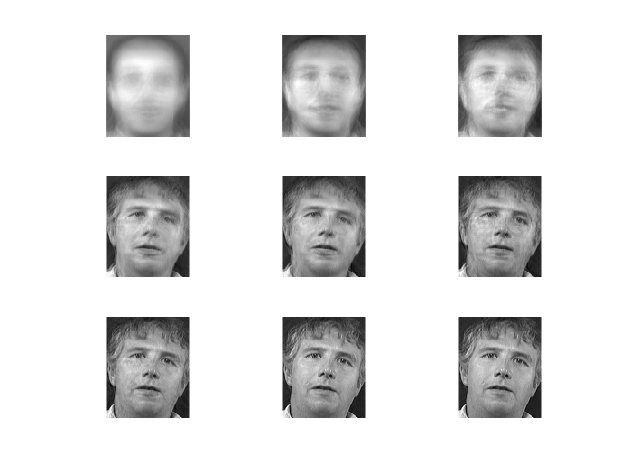

fp = 14

fn = 33

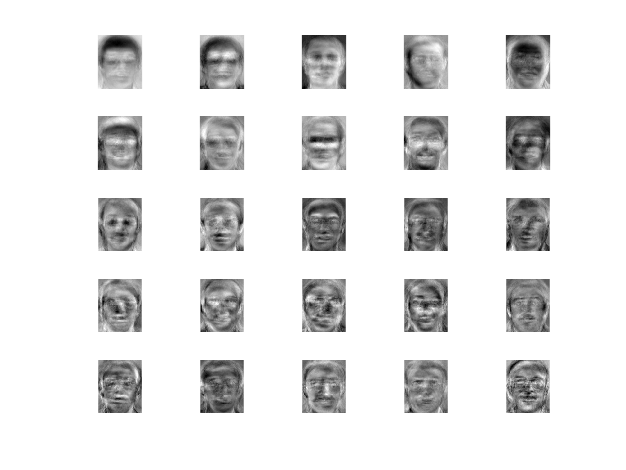

imagefiles = dir("ORL/ORL/*/*.pgm");
nfiles = length(imagefiles);
train = double(zeros(92*112, 1));
test = double(zeros(92*112, 1));
outside = double(zeros(92*112, 1));
train_index = 1;
test_index = 1;
out_index = 1;
count = [];
for i=1:400
    if i<=320
        if mod(i-1, 10) <6
            im = double(imread("ORL/ORL/s"+int2str(floor((i-1)/10)+1)+"/"+imagefiles(i).name));
            train(:, train_index) = reshape(im', 1, [])';
            train_index=train_index+1;
        else
            im = double(imread("ORL/ORL/s"+int2str((floor((i-1)/10)+1))+"/"+imagefiles(i).name));
            test(:, test_index) = reshape(im',1,[])';
            test_index=test_index+1;
        end
    else
        im = double(imread("ORL/ORL/s"+int2str(floor((i-1)/10)+1)+"/"+imagefiles(i).name));
        outside(:, out_index) = reshape(im', 1, [])';
        out_index=out_index+1;
    end
end
ks =[1, 2, 3, 5, 10, 15, 20, 30, 50, 75, 100, 150, 170];
% The last argument is 0 for eig with X^TX, 1 for svd and 2 for eig
[acc_rate, coeff] = PCA_f(train, test, outside, ks, 1);

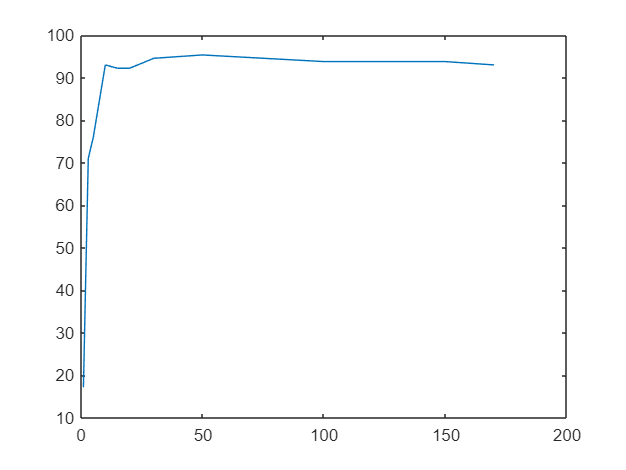

fig = figure;
plot(ks, acc_rate);

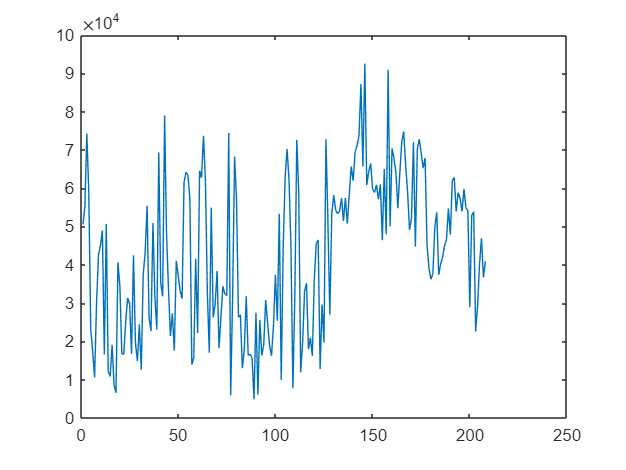

V = uint32(1):uint32(400-192);
%plot(V, coeff);